clear
clc
close all

%Defining the vehicle parameters(kg, N/m, Ns/m)

m1=25;
m2=350;
m3=75;
c1=220000;
c2=18000;
c3=80000;
d2=1200;
d3=500;


%Define State-Space Matrixes
A_Modell=[0 0 0 1 0 0;
          0 0 0 0 1 0;
          0 0 0 0 0 1;
          (-c1-c2)/m1 c2/m1 0 -d2/m1 d2/m1 0;
          c2/m2 (-c2-c3)/m2 c3/m2 d2/m2 (-d2-d3)/m2 d3/m2;
          0 c3/m3 -c3/m3 0 d3/m3 -d3/m3];

disp(A_Modell)

   1.0e+03 *

         0         0         0    0.0010         0         0
         0         0         0         0    0.0010         0
         0         0         0         0         0    0.0010
   -9.5200    0.7200         0   -0.0480    0.0480         0
    0.0514   -0.2800    0.2286    0.0034   -0.0049    0.0014
         0    1.0667   -1.0667         0    0.0067   -0.0067




B_Modell=[0;
          0;
          0;
          c1/m1;
          0;
          0];

disp(B_Modell)

           0
           0
           0
        8800
           0
           0



      
C_Modell=[1 0 0 0 0 0;
          0 1 0 0 0 0;
          0 0 1 0 0 0;
          0 0 0 1 0 0;
          0 0 0 0 1 0;
          0 0 0 0 0 1;
          0 0 0 0 0 0];

disp(C_Modell)

     1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1
     0     0     0     0     0     0




D_Modell=[0;
          0;
          0;
          0;
          0;
          0;
          1];

disp(D_Modell)

     0
     0
     0
     0
     0
     0
     1




Modellss=ss(A_Modell,B_Modell,C_Modell,D_Modell);
%Extracting transfer function
[num,den]=ss2tf(A_Modell,B_Modell,C_Modell,D_Modell)

num = 	1.0e+08 *

         0         0    0.0001    0.0010    0.1205    0.3520    4.8274
         0         0         0    0.0003    0.0065    0.3520    4.8274
         0         0         0         0    0.0020    0.3520    4.8274
         0    0.0001    0.0010    0.1205    0.3520    4.8274         0
         0         0    0.0003    0.0065    0.3520    4.8274   -0.0000
         0         0         0    0.0020    0.3520    4.8274   -0.0000
    0.0000    0.0000    0.0001    0.0017    0.1304    0.3520    4.8274


den = 	1.0e+08 *

    0.0000    0.0000    0.0001    0.0017    0.1304    0.3520    4.8274



[Gz1_num,Gz1_den]=ss2tf(A_Modell,B_Modell,C_Modell(1,:),D_Modell(1,:));
Gz1=tf(Gz1_num,Gz1_den);
Gz1=minreal(Gz1)

Gz1 =
 
             8800 s^4 + 1.014e05 s^3 + 1.205e07 s^2 + 3.52e07 s + 4.827e08
  -----------------------------------------------------------------------------------
  s^6 + 59.52 s^5 + 1.128e04 s^4 + 1.734e05 s^3 + 1.304e07 s^2 + 3.52e07 s + 4.827e08
 
Continuous-time transfer function.




[Gz2_num,Gz2_den]=ss2tf(A_Modell,B_Modell,C_Modell(2,:),D_Modell(2,:));
Gz2=tf(Gz2_num,Gz2_den);
Gz2=minreal(Gz2)

Gz2 =
 
                  3.017e04 s^3 + 6.537e05 s^2 + 3.52e07 s + 4.827e08
  -----------------------------------------------------------------------------------
  s^6 + 59.52 s^5 + 1.128e04 s^4 + 1.734e05 s^3 + 1.304e07 s^2 + 3.52e07 s + 4.827e08
 
Continuous-time transfer function.




[Gz3_num,Gz3_den]=ss2tf(A_Modell,B_Modell,C_Modell(3,:),D_Modell(3,:));
Gz3=tf(Gz3_num,Gz3_den);
Gz3=minreal(Gz3)

Gz3 =
 
                          2.011e05 s^2 + 3.52e07 s + 4.827e08
  -----------------------------------------------------------------------------------
  s^6 + 59.52 s^5 + 1.128e04 s^4 + 1.734e05 s^3 + 1.304e07 s^2 + 3.52e07 s + 4.827e08
 
Continuous-time transfer function.



% [Gz7_num,Gz7_den]=ss2tf(A_Modell,B_Modell,C_Modell(7,:),D_Modell(7,:));
% Gz7=tf(Gz7_num,Gz7_den);
% Gz7=minreal(Gz7)

%Defining initial conditions
X0=[0;
    0;
    0;
    0;
    0;
    0];

%Caculating theoretical eigen-fraquencies
fm1=sqrt((c1+c2)/m1-power(d2,2)/(power(2*m1,2)))/(2*pi)

fm1 = 15.0517

fm2=sqrt(c2/(m2+m3)-power(d2,2)/(power(2*(m2+m3),2)))/(2*pi)

fm2 = 1.0111

fm3=sqrt((c3)/m3-power(d3,2)/(power(2*m3,2)))/(2*pi)

fm3 = 5.1708

%Setting modeling parameters
tstep=0.001;
f0=0;
f1=30;
ftrans=1;
fstep=0.1;
tfinal=(f1-f0)/fstep;
ttrans=(ftrans-f0)/fstep;
H=0.1;

%Calulating System Gain
f_span=f0:fstep:f1;
Gain= freqresp(Modellss,f_span,'Hz')

Gain = Gain(:,:,1) =

   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   1.0000 + 0.0000i


Gain(:,:,2) =

   1.0008 - 0.0000i
   1.0102 - 0.0004i
   1.0106 - 0.0004i
   0.0000 + 0.6288i
   0.0002 + 0.6347i
   0.0003 + 0.6350i
   1.0000 + 0.0000i


Gain(:,:,3) =

   1.0034 - 0.0000i
   1.0419 - 0.0034i
   1.0435 - 0.0034i
   0.0000 + 1.2609i
   0.0042 + 1.3093i
   0.0043 + 1.3113i
   1.0000 + 0.0000i


Gain(:,:,4) =

   1.0080 - 0.0001i
   1.0986 - 0.0125i
   1.1023 - 0.0126i
   0.0002 + 1.8999i
   0.0236 + 2.0708i
   0.0238 + 2.0777i
   1.0000 + 0.0000i


Gain(:,:,5) =

   1.0152 - 0.0004i
   1.1867 - 0.0343i
   1.1938 - 0.0346i
   0.0011 + 2.5515i
   0.0861 + 2.9826i
   0.0869 + 3.0003i
   1.0000 + 0.0000i


Gain(:,:,6) =

   1.0263 - 0.0016i
   1.3170 - 0.0815i
   1.3292 - 0.0825i
   0.0049 + 3.2242i
   0.2559 + 4.1374i
   0.2591 + 4.1760i
   1.0000 + 0.0000i


Gain(:,:,7) =

   1.0431 - 0.0050i
   1.5046 - 0.18

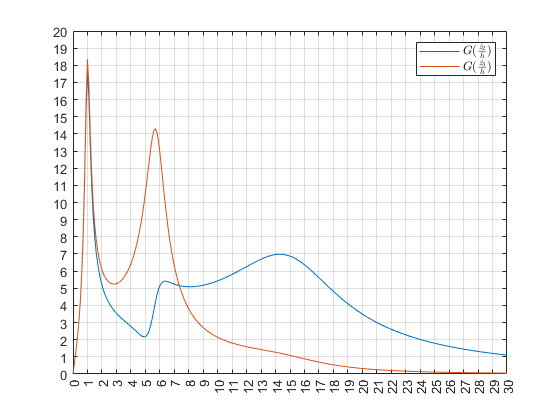

gain=squeeze(Gain(5:6,1,:));
plot(f_span,abs(gain));
xticks(f0:1:f1);
yticks(0:1:20);
grid on;
l_gain=legend('$G(\frac{\dot{z_2}}{h})$','$G(\frac{\dot{z_3}}{h})$');
set(l_gain,'Interpreter','latex')

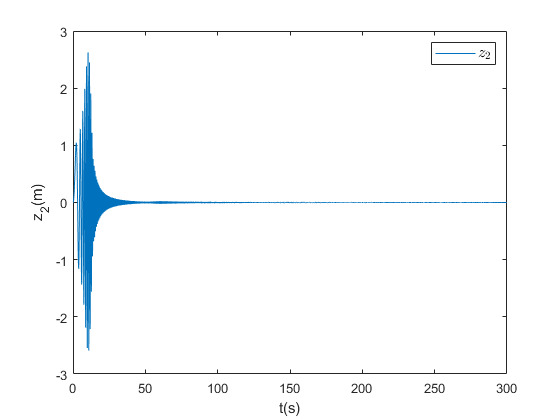


% for i=1:length(gain)
% z2z3(1,i)=abs(gain(1,i))/abs(gain(2,i));
% end
% plot(f_span,z2z3);


%Running Simulink model from .m file and Extracting data
zh=sim('modell2.slx').get('zh');
t=zh.Time;
z1=zh.Data(:,1);
z2=zh.Data(:,2);
z3=zh.Data(:,3);
z1dot=zh.Data(:,4);
z2dot=zh.Data(:,5);
z3dot=zh.Data(:,6);
h=zh.Data(:,7);

%generate z2ddot
z2ddot=gradient(z2dot,t);

%Creating time-frequency interface
f=f0+t*fstep;

%Plotting variables

figure();
Z2=plot(t,z2);
l2=legend('$z_2$');
set(l2,'Interpreter','latex','fontsize',12);
xlabel('t(s)');
ylabel('z_2(m)');

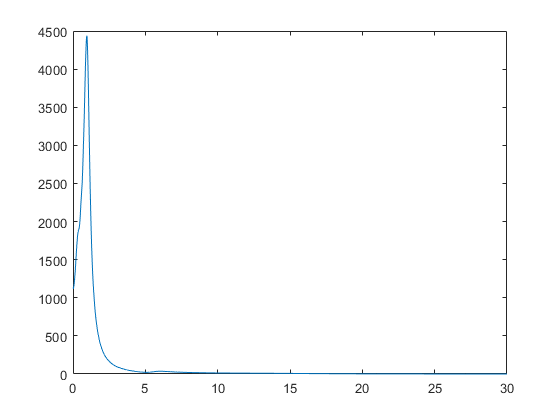

figure();
Z2_f=fft(z2,length(z2));
FTf1=linspace(0,1/tstep,length(z2));
plot(FTf1,abs(Z2_f(1:length(z2)))) 
xlim([0,30])

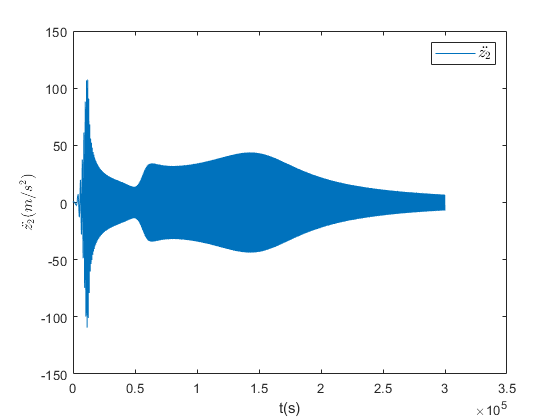


figure();
Z2ddot_T=plot(z2ddot);
l2ddot=legend('$\ddot{z_2}$');
set(l2ddot,'Interpreter','latex','fontsize',12);
xlabel('t(s)');
ylabel('$\ddot{z_2}(m/s^2)$','interpreter','latex');

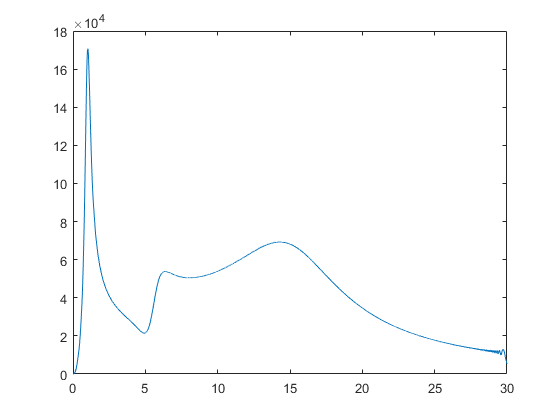

figure();
Z2ddot_f=fft(z2ddot,length(z2ddot));
FTf2=linspace(0,1/tstep,length(z2ddot));
plot(FTf2,abs(Z2ddot_f(1:length(z2ddot)))) 
xlim([0,30])